# **Detecció de presència de jugadors del Barça en la escena.**

### clear

clc;
clear;
close all;


### Calculem histograma de colors dels models de tots el equips 

%% Calcul d'histogrames models
BarcelonaIm= imread("barcelona/31.jpg");
%imshow(BarcelonaIm);
%rect = getrect;
%BarcelonaIm = imcrop(BarcelonaIm,rect);
BarcelonaIm = imcrop(BarcelonaIm,[166	64	75	111]);
BarcelonaIm = normalitzar(BarcelonaIm);
hBarcelona = getHist(BarcelonaIm);

AcmilanIm= imread("acmilan/18.jpg");
AcmilanIm = imcrop(AcmilanIm,[42.0000000000000	136	132.000000000000	81]);
%imshow(AcmilanIm);
%rect = getrect;
%AcmilanIm = imcrop(AcmilanIm,rect);
AcmilanIm = normalitzar(AcmilanIm);
hAcmilan = getHist(AcmilanIm);

ChelseaIm= imread("chelsea/04.jpg");
%imshow(ChelseaIm);
%rect = getrect;
%ChelseaIm = imcrop(ChelseaIm,rect);
ChelseaIm = imcrop(ChelseaIm,[188.000000000000	100.000000000000	63	51]);
ChelseaIm = normalitzar(ChelseaIm);
hChelsea = getHist(ChelseaIm);

JuventusIm= imread("juventus/04.jpg");
JuventusIm = imcrop(JuventusIm,[30 92 45 24]);
JuventusIm = normalitzar(JuventusIm);
hJuventus = getHist(JuventusIm);

LiverpoolIm= imread("liverpool/08.jpg");
%imshow(LiverpoolIm);
%rect = getrect;
%LiverpoolIm = imcrop(LiverpoolIm,rect);
LiverpoolIm = imcrop(LiverpoolIm,[61.0000000000000	88.0000000000001	71.0000000000000	51]);
LiverpoolIm = normalitzar(LiverpoolIm);
hLiverpool = getHist(LiverpoolIm);

MadridIm= imread("madrid/01.jpg");
MadridIm = imcrop(MadridIm,[70 194 59 47]);
MadridIm = normalitzar(MadridIm);
hMadrid = getHist(MadridIm);

PsvIm= imread("psv/01.jpg");
PsvIm = imcrop(PsvIm,[99 125 39 24]);
PsvIm = normalitzar(PsvIm);
hPsv = getHist(PsvIm);

VilarealIm= imread("vilareal/07.jpg");
VilarealIm = imcrop(VilarealIm,[531 131 63 155]);
VilarealIm = normalitzar(VilarealIm);
hVilareal = getHist(VilarealIm);

%bar(hBarcelona);

### Obtenim puntuacions del cada equip i puntuació total

%Obtenim puntuacions de tots els equips
myFolder = 'barcelona';
filePattern = fullfile(myFolder, '*.jpg');
jpegFiles = dir(filePattern);
encerts=0;
for k = 1:length(jpegFiles)
    baseFileName = jpegFiles(k).name;
    fullFileName = fullfile(myFolder, baseFileName);
    imageArray = imread(fullFileName);
    model = imageArray;
    index = teamscore(model,hBarcelona,hAcmilan,hChelsea,hJuventus,hLiverpool,hMadrid,hPsv,hVilareal);
    if(index==0)
        encerts=encerts+1;
    end
end
barcelona_score=encerts/36;


myFolder = 'madrid';
filePattern = fullfile(myFolder, '*.jpg');
jpegFiles = dir(filePattern);
encerts=0;
for k = 1:length(jpegFiles)
    baseFileName = jpegFiles(k).name;
    fullFileName = fullfile(myFolder, baseFileName);
    imageArray = imread(fullFileName);
    model = imageArray;
    index = teamscore(model,hBarcelona,hAcmilan,hChelsea,hJuventus,hLiverpool,hMadrid,hPsv,hVilareal);
    if(index==5)
        encerts=encerts+1;
    end
end
madrid_score=encerts/36;

myFolder = 'acmilan';
filePattern = fullfile(myFolder, '*.jpg');
jpegFiles = dir(filePattern);
encerts=0;
for k = 1:length(jpegFiles)
    baseFileName = jpegFiles(k).name;
    fullFileName = fullfile(myFolder, baseFileName);
    imageArray = imread(fullFileName);
    model = imageArray;
    index = teamscore(model,hBarcelona,hAcmilan,hChelsea,hJuventus,hLiverpool,hMadrid,hPsv,hVilareal);
    if(index==1)
        encerts=encerts+1;
    end
end
acmilan_score=encerts/36;

myFolder = 'chelsea';
filePattern = fullfile(myFolder, '*.jpg');
jpegFiles = dir(filePattern);
encerts=0;
for k = 1:length(jpegFiles)
    baseFileName = jpegFiles(k).name;
    fullFileName = fullfile(myFolder, baseFileName);
    imageArray = imread(fullFileName);
    model = imageArray;
    index = teamscore(model,hBarcelona,hAcmilan,hChelsea,hJuventus,hLiverpool,hMadrid,hPsv,hVilareal);
    if(index==2)
        encerts=encerts+1;
    end
end
chelsea_score=encerts/36;


myFolder = 'juventus';
filePattern = fullfile(myFolder, '*.jpg');
jpegFiles = dir(filePattern);
encerts=0;
for k = 1:length(jpegFiles)
    baseFileName = jpegFiles(k).name;
    fullFileName = fullfile(myFolder, baseFileName);
    imageArray = imread(fullFileName);
    model = imageArray;
    index = teamscore(model,hBarcelona,hAcmilan,hChelsea,hJuventus,hLiverpool,hMadrid,hPsv,hVilareal);
    if(index==3)
        encerts=encerts+1;
    end
end
juventus_score=encerts/36;


myFolder = 'liverpool';
filePattern = fullfile(myFolder, '*.jpg');
jpegFiles = dir(filePattern);
encerts=0;
for k = 1:length(jpegFiles)
    baseFileName = jpegFiles(k).name;
    fullFileName = fullfile(myFolder, baseFileName);
    imageArray = imread(fullFileName);
    model = imageArray;
    index = teamscore(model,hBarcelona,hAcmilan,hChelsea,hJuventus,hLiverpool,hMadrid,hPsv,hVilareal);
    if(index==4)
        encerts=encerts+1;
    end
end
liverpool_score=encerts/36;


myFolder = 'psv';
filePattern = fullfile(myFolder, '*.jpg');
jpegFiles = dir(filePattern);
encerts=0;
for k = 1:length(jpegFiles)
    baseFileName = jpegFiles(k).name;
    fullFileName = fullfile(myFolder, baseFileName);
    imageArray = imread(fullFileName);
    model = imageArray;
    index = teamscore(model,hBarcelona,hAcmilan,hChelsea,hJuventus,hLiverpool,hMadrid,hPsv,hVilareal);
    if(index==6)
        encerts=encerts+1;
    end
end
psv_score=encerts/36;

myFolder = 'vilareal';
filePattern = fullfile(myFolder, '*.jpg');
jpegFiles = dir(filePattern);
encerts=0;
for k = 1:length(jpegFiles)
    baseFileName = jpegFiles(k).name;
    fullFileName = fullfile(myFolder, baseFileName);
    imageArray = imread(fullFileName);
    model = imageArray;
    index = teamscore(model,hBarcelona,hAcmilan,hChelsea,hJuventus,hLiverpool,hMadrid,hPsv,hVilareal);
    if(index==7)
        encerts=encerts+1;
    end
end
vilareal_score=encerts/36;

total_score=acmilan_score+barcelona_score+chelsea_score+juventus_score+liverpool_score;
total_score=total_score+madrid_score+psv_score+vilareal_score;
total_score=total_score/8;

disp('acmilan score:');

acmilan score:


disp(acmilan_score);

    0.7222



disp('barcelona score:');

barcelona score:


disp(barcelona_score);

    0.6389



disp('chelsea score:');

chelsea score:


disp(chelsea_score);

    0.6667



disp('juventus score:');

juventus score:


disp(juventus_score);

    0.3333



disp('liverpool score:');

liverpool score:


disp(liverpool_score);

    0.3611



disp('madrid score:');

madrid score:


disp(madrid_score);

    0.6667



disp('psv score:');

psv score:


disp(psv_score);

    0.3889



disp('vilareal score:');

vilareal score:


disp(vilareal_score);

    0.5556



disp('total score:');

total score:


disp(total_score);

    0.5417



**Test**

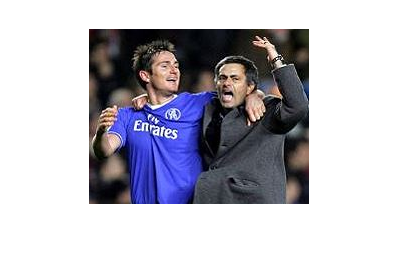

% VIm= imread("vilareal/07.jpg");
% imshow(VIm);
% %rect = getrect;
% %VIm = imcrop(VIm,rect);
% VIm = imcrop(VIm,[531 131 63 155]);
% VIm = normalitzar(VIm);
% hV = getHist(VIm);
% normhV = normalitzarHist(hV);
% h = bar3(normhV);
% h(1).FaceColor = 'r';
% h(2).FaceColor = 'b';

model = imread("chelsea/16.jpg");
imshow(model);

getPuntuation(model, hVilareal);
ind = teamscore(model,hBarcelona,hAcmilan,hChelsea,hJuventus,hLiverpool,hMadrid,hPsv,hVilareal)

ind = 2

index2team(ind)

ans = 'chelsea'

#### *Auxiliar functions*

Funció per calcular Chi-Square distance

function res = chiSquare(h1,h2)
    qi = sum(h1,'all');
    vi = sum(h2,'all');
    Q = h1./qi;
    V = h2./vi;
    N = (Q-V).^2;
    D = (Q+V);
    dist = N./D;
    res = sum(dist,'all','omitnan')/2;
end

Funció per calcular intersecció d'histogrames

function res = interseccio(h1,h2)   %%ESBORRAR SI NO NECESARIA
    qi = sum(h1,'all');
    vi = sum(h2,'all');
    Q = h1./qi;
    V = h2./vi;
    inter = min(Q,V);
    res = sum(inter,'all','omitnan')/2;
end

Funció per normalitzar una imatge

function[Norm] = normalitzar(Im)
 R = double(Im(:,:,1));
 G = double(Im(:,:,2));
 B = double(Im(:,:,3));
 I = (R+G+B);
 r = R./I;
 g = G./I;
 b = B./I;
 %Norm = imgaussfilt(cat(3,r,g,b));
 Norm = (cat(3,r,g,b));
 Norm(isnan(Norm)) = 0;
 
end

   Funcio per obtenir el equip al que pertany el model

function score= teamscore(model,hBarcelona,hAcmilan,hChelsea,hJuventus,hLiverpool,hMadrid,hPsv,hVilareal)
        index=0;
        resBarcelona=getPuntuation(model,hBarcelona);
        bestscore=resBarcelona;
        resMilan=getPuntuation(model,hAcmilan);
        if(resMilan<bestscore)
            bestscore=resMilan;
            index=1;
        end
        resChelsea=getPuntuation(model,hChelsea);
        if(resChelsea<bestscore)
            bestscore=resChelsea;
            index=2;
        end
        resJuventus=getPuntuation(model,hJuventus);
        if(resJuventus<bestscore)
            bestscore=resJuventus;
            index=3;
        end
        resLiverpool=getPuntuation(model,hLiverpool);
        if(resLiverpool<bestscore)
            bestscore=resLiverpool;
            index=4;
        end
        resMadrid=getPuntuation(model,hMadrid);
        if(resMadrid<bestscore)
            bestscore=resMadrid;
            index=5;
        end
        resPsv=getPuntuation(model,hPsv);
        if(resPsv<bestscore)
            index=6;
        end
        resVilareal=getPuntuation(model,hVilareal);
        if(resVilareal<bestscore)
            index=7;
        end
        score=index;
end

Funcio per obtenir la puntuacio del millor fragment d'una Imatge respecte el model

function bestscore = getPuntuation(model,hModel)
        grid = 5;
        [row, col, channels] = size(model);
        bestscore=2;
        for i=0:grid-1
            for j=0:grid-1
                cell = imcrop(model, [j*col/grid i*row/grid col/grid row/grid]); 
                cell = normalitzar(cell);           
                hC = getHist(cell);
                res = chiSquare(hModel,hC);
                res2 = interseccio(hModel,hC); %ESBORRAR SI NO NECESARIA
                if(bestscore>res)
                    bestscore=res;
                end
         
            end
        end
end

 Funcio per obtenir el histograma a partir d'una Imatge

function h = getHist(Im)
    R = double(Im(:,:,1));
    G = double(Im(:,:,2));
    B = double(Im(:,:,3));
    I = (R+G+B);
    R = R./I;
    %G = G./I;
    B = B./I;
    R(isnan(R)) = 0;
    B(isnan(B)) = 0;
    %G(isnan(G)) = 0;
    hR = imhist(R,32);
    
    %hG = imhist(G,32); % G= 1 -R - B
    hB = imhist(B,32);
    h = normalitzarHist(cat(2,hR,hB));
end

Funcio per normalitzar Histograma

function[Norm] = normalitzarHist(Hist)
 total1 = sum(Hist(:,1));
 total2 = sum(Hist(:,2));
 
 h1 = arrayfun(@(x) x/total1, Hist(:,1));
 h2 = arrayfun(@(x) x/total2, Hist(:,2));
 
 Norm = cat(2,h1,h2);
end

Funcio per convertir el index en el equip pertinent

function team = index2team(ind)
    switch ind
        case 1
            team = 'milan';
        case 2
            team = 'chelsea';
        case 3
            team = 'juventus';
        case 4
            team = 'liverpool';
        case 5
            team = 'madrid';
        case 6
            team = 'psv';
        case 7
            team = 'vilareal';
        otherwise
            team = 'barcelona';
    end
end